%prep 1
clf
s=tf("s");
G = 32/(s+8)

G =
 
   32
  -----
  s + 8
 
Continuous-time transfer function.
Model Properties


%bode(G)
hold on
%Kp = 2
%bode(G*Kp)
Kp = 0.5

Kp = 0.5000

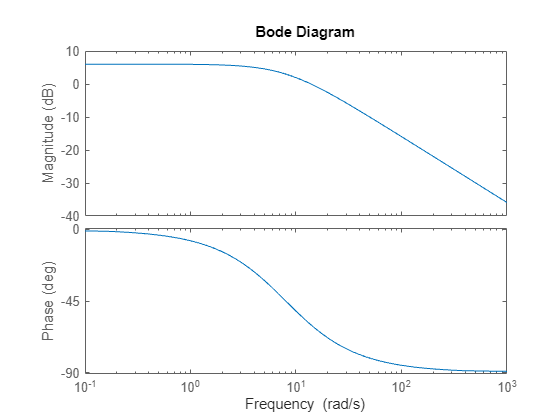

bode(G*Kp)

%prep4
clf
G = 8/(s*(s/10+1))

G =
 
      80
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


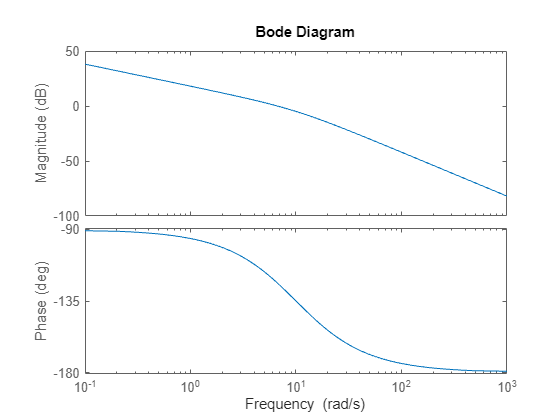

bode(G)

% Wc = 6.66 => Phase margin = 56.3    (-123.7)
% Fig 5.11 gives zeta = 0.5
% Fig 5.12 gives WcTr = 1.29   Tr <= 0.06s gives
% Wc,d = 21.5 => -155 deg Phase margin,c,d = 25
% need to add 56.3-25 = 31.3 
% 31.3 + 8 (from the lag)
% ?
% ?
% 1/|Flead||G(i*21.5)| =  1/0.34 = typ = 2.8
Kp = 2.8; % 
D = 0.1;
b = 0.23;
I = 0.46;
y = 0.028;
F = Kp * ((D*s+1)/(b*D*s+1)) * ((I*s+1)/(I*s+y))

F =
 
    0.1288 s^2 + 1.568 s + 2.8
  ------------------------------
  0.01058 s^2 + 0.4606 s + 0.028
 
Continuous-time transfer function.
Model Properties


%F = K * ((D*s+1)/(b*D*s+1)) * ((I*s+1)/(I*s+y))
Gw = feedback(G,F)

Gw =
 
              0.8464 s^2 + 36.85 s + 2.24
  ----------------------------------------------------
  0.01058 s^4 + 0.5664 s^3 + 14.94 s^2 + 125.7 s + 224
 
Continuous-time transfer function.
Model Properties


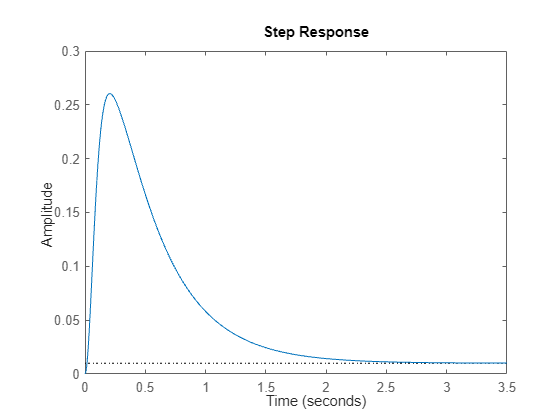

step(Gw)

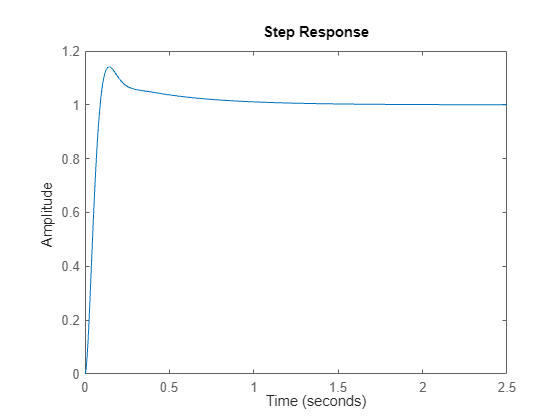

step((G*F)/(1+G*F))